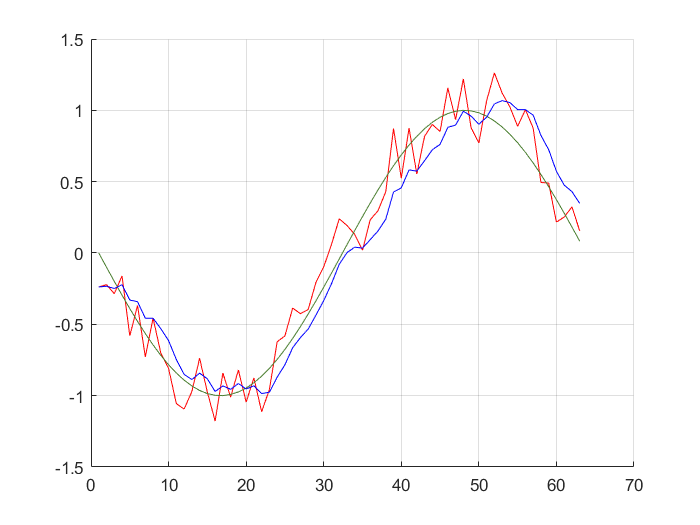

t = (-pi:0.1:pi);
x = sin(t);
hold on
grid on

y = awgn(x, 15);
plot(y, 'color', 'r');
plot(x, 'color', '0.3 0.5 0.2');

% Exponential Smoothing
s = zeros;
alpha = 0.3;
s(1) = y(1);
for i = 2:length(y)
    s(i) = s(i-1) + alpha * (y(i) - s(i-1));
end
plot(s, 'color', 'blue');